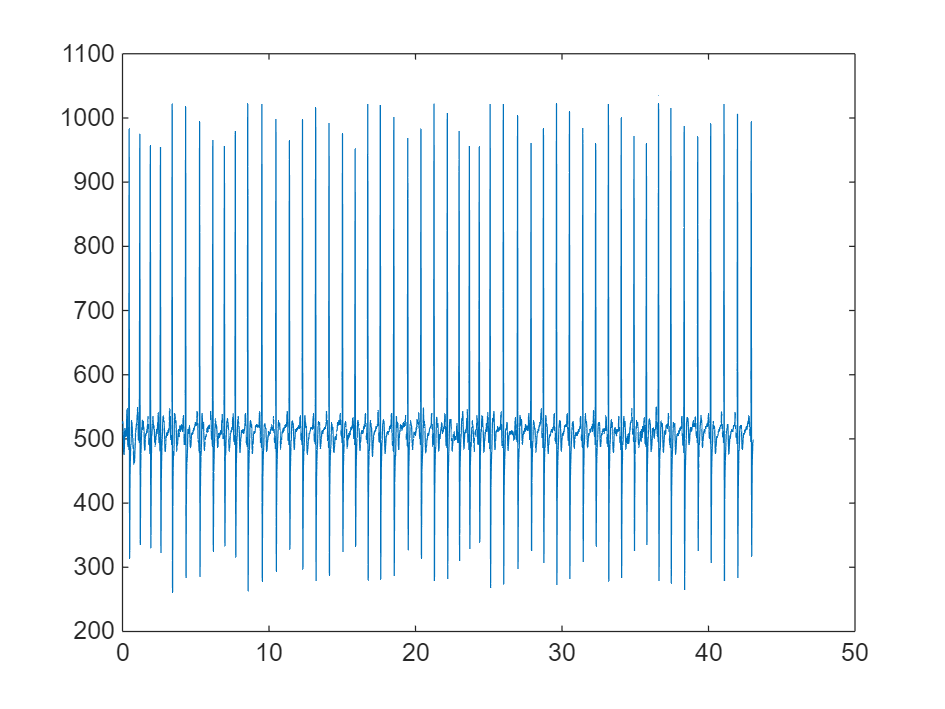

ECG_filename = 'chest_rest_trial1.txt';

ECG_raw_data = readmatrix(ECG_filename);

ECG_data = ECG_raw_data(:,7);

ECG_fs = 1000;

ECG_ts = 1./ECG_fs;

ECG_time = ECG_ts:ECG_ts:(length(ECG_data)*ECG_ts);

figure;
plot(ECG_time,ECG_data);


ECG_clip_ind = (ECG_time >= 10) & (ECG_time <= 40);

ECG_clip_time = ECG_time(ECG_clip_ind);
ECG_clip_data = ECG_data(ECG_clip_ind);


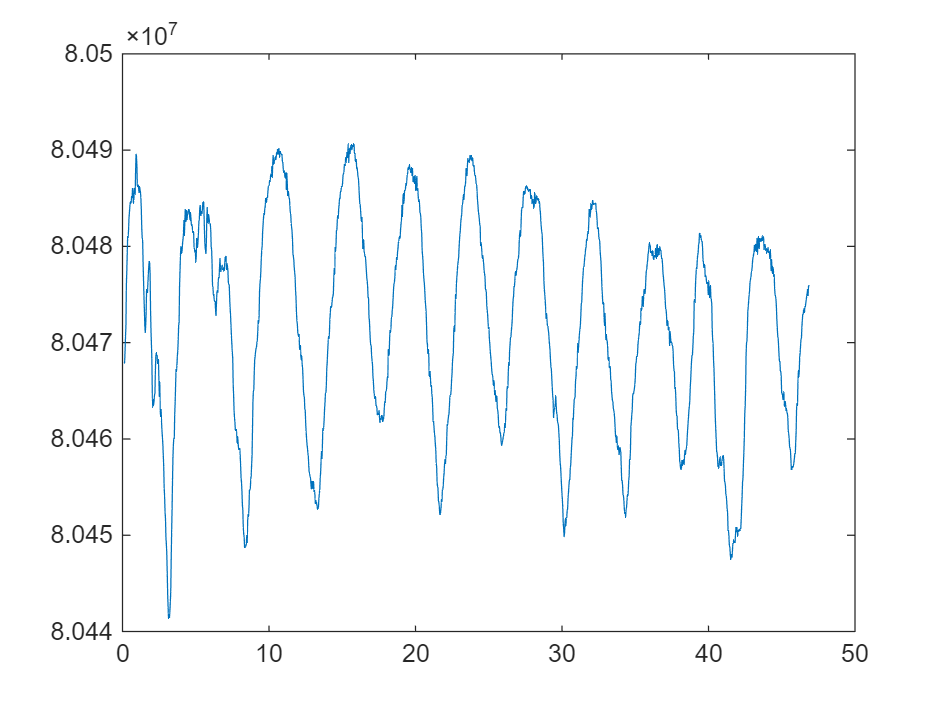


sensor_filename = 'chest_rest_trial1.csv';
raw_data = readtable(sensor_filename,'Delimiter',',');

% Take care of header chunk
raw_time = raw_data{:,1};
[row, ~] = find(isnan(raw_time));

if ~isempty(row)
    % double check to make sure nan is from the header instead of data
    if (row(end) - row(1) + 1) == length(row)

        raw_data = raw_data(row(end)+1:end,:); % clip header
    end
end
raw_data(end,:) = [];   % get rid of last line in case of incomplete data log

% Raw time & data
time = raw_data{:,1}./1000; % in seconds
data = raw_data{:,2};

figure;
plot(time,data);

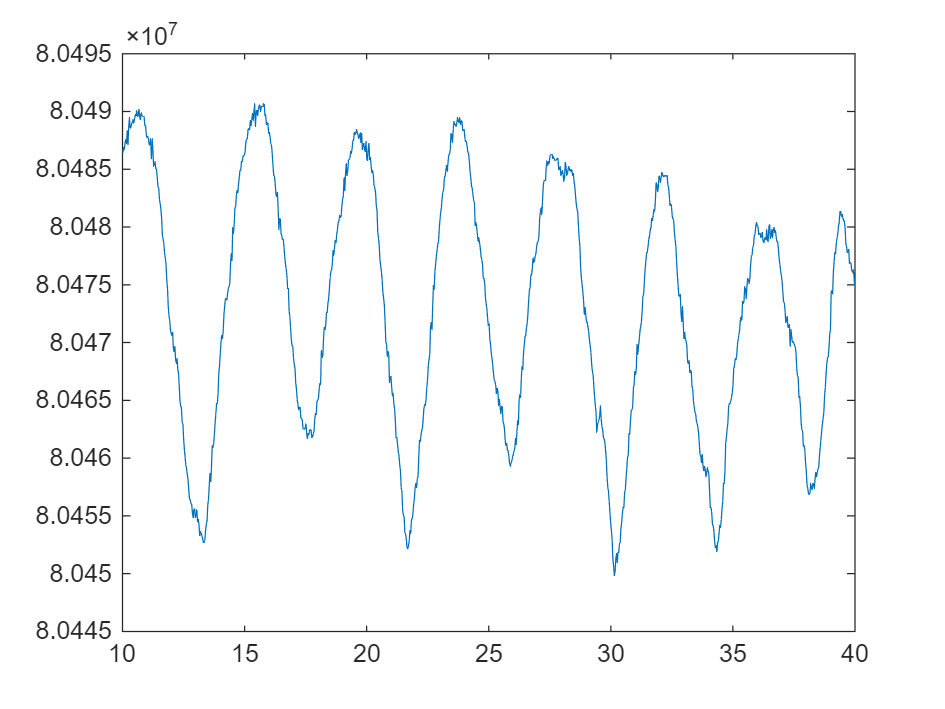


pump_idx = (time >= 10) & (time <= 40);

time_pump = time(pump_idx);
data_pump = data(pump_idx);

figure;
plot(time_pump,data_pump);

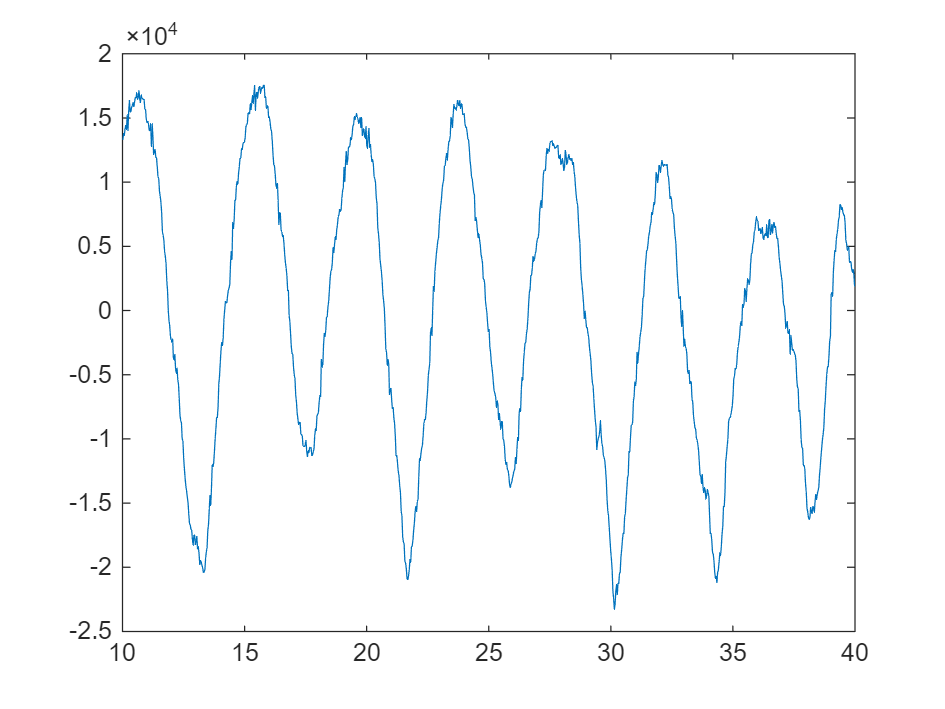


mean_data_pump = mean(data_pump);
delta_data_pump = data_pump - mean_data_pump;

mag_data_pump = max(delta_data_pump) - min(delta_data_pump);

figure;
plot(time_pump,delta_data_pump)


ts = 0.03;
fs = 1/ts;

rs_time = 1:ts:350;

[~,end_idx] = min(abs(rs_time - time_pump(end)));
[~,stt_idx] = min(abs(rs_time - time_pump(1)));


rs_time  = rs_time(stt_idx:end_idx);
rs_data = interp1(time,data,rs_time);

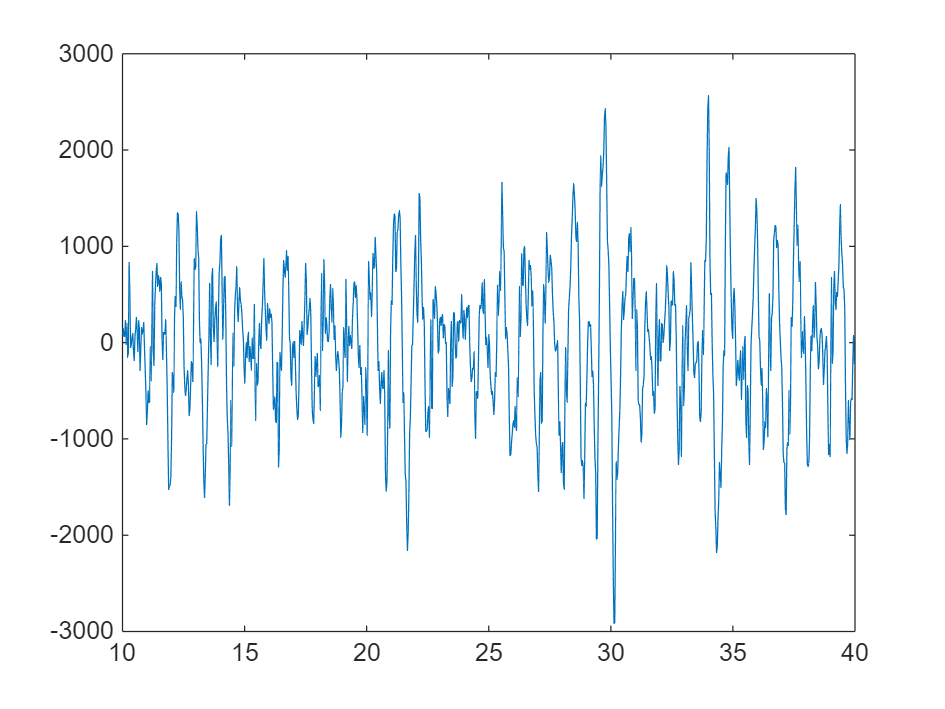

% High pass to try to remove baseline

cutoff_freq = 0.8;    % Cutoff frequency in Hz
filter_order = 4;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
hp_data= filtfilt(b, a, rs_data);

figure;
plot(rs_time,hp_data)

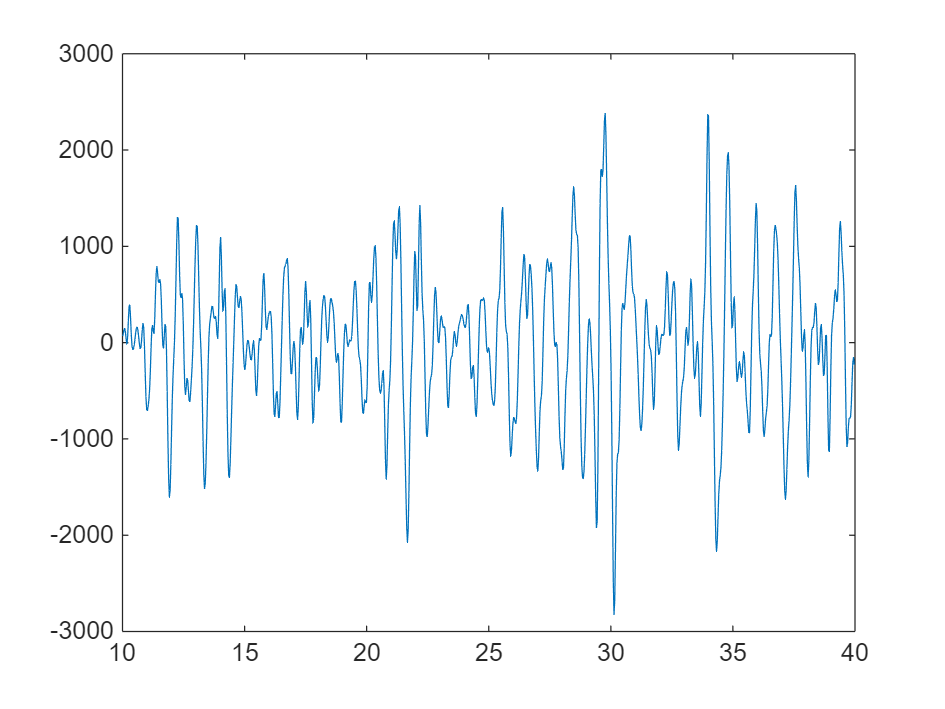

% Low pass to try to remove noise

cutoff_freq = 6;    % Cutoff frequency in Hz
filter_order = 5;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');
bp_data= filtfilt(b, a, hp_data);

figure;
plot(rs_time,bp_data)

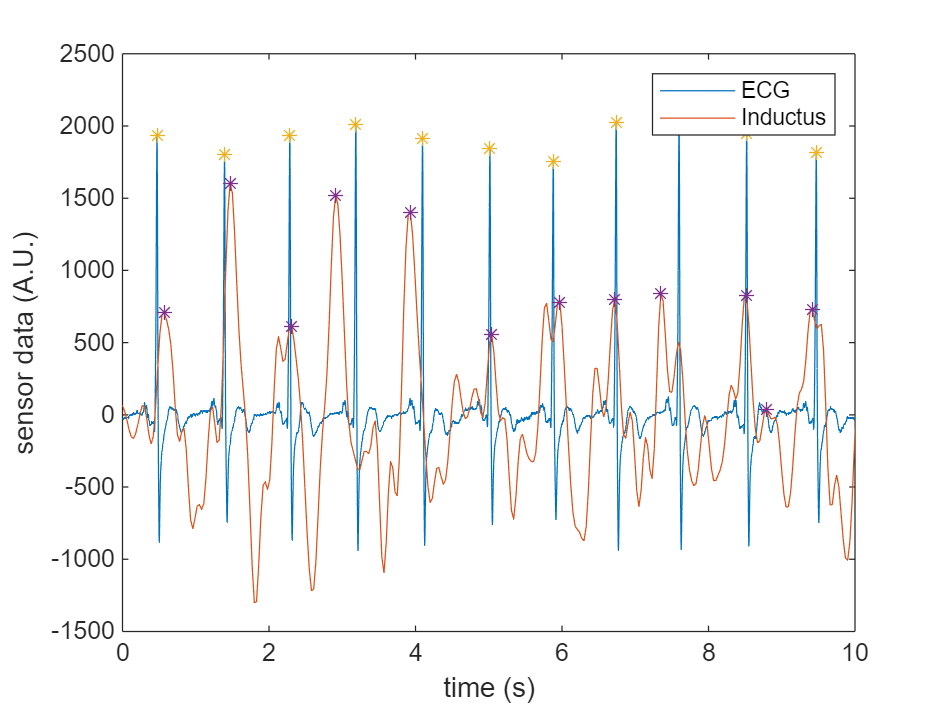

magnified_ECG_data = 4*(ECG_clip_data - mean(ECG_clip_data));

[sensor_pk_vals, sensor_pk_locs] = findpeaks(-bp_data, rs_time,'MinPeakWidth', 0.13);
[ECG_pk_vals, ECG_pk_locs] = findpeaks(magnified_ECG_data, ECG_clip_time,'MinPeakHeight', 600);

figure;
plot(ECG_clip_time-10,magnified_ECG_data)
hold on
plot(rs_time-10.45,-bp_data)
plot(ECG_pk_locs-10, ECG_pk_vals,'*')
plot(sensor_pk_locs-10.45, sensor_pk_vals,'*')
hold off
xlim([0 10])
legend('ECG','Inductus')
xlabel('time (s)')
ylabel('sensor data (A.U.)')

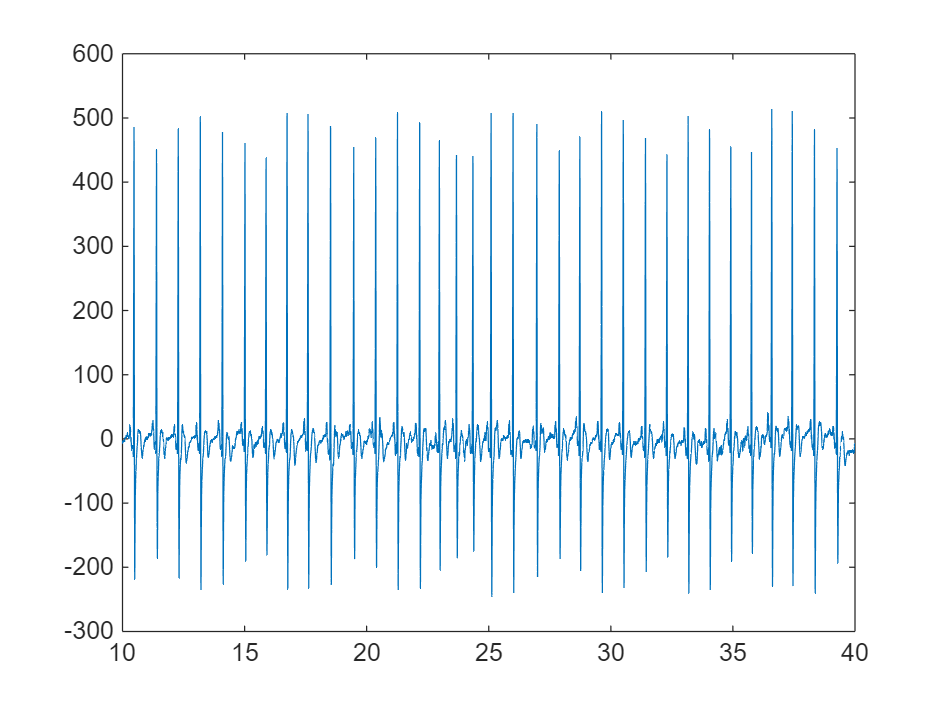

% High pass to try to remove baseline

cutoff_freq = 0.1;    % Cutoff frequency in Hz
filter_order = 4;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(ECG_fs/2), 'high');
ECG_hp_data= filtfilt(b, a, ECG_clip_data);

figure;
plot(ECG_clip_time,ECG_hp_data)

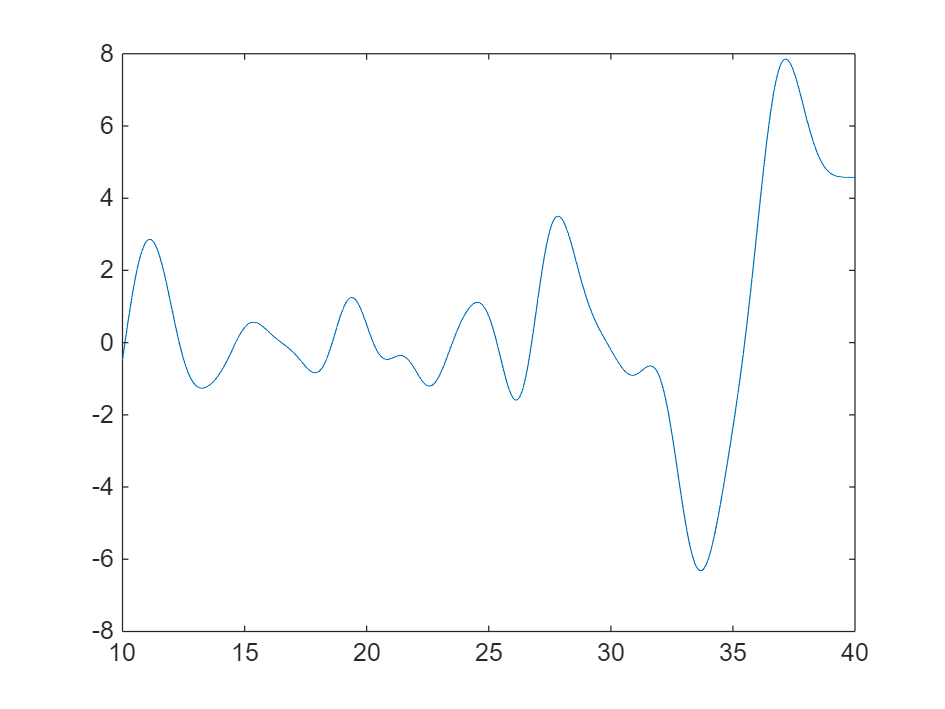

% Low pass to try to remove noise

cutoff_freq = 0.4;    % Cutoff frequency in Hz
filter_order = 5;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(ECG_fs/2), 'low');
ECG_bp_data= filtfilt(b, a, ECG_hp_data);

figure;
plot(ECG_clip_time,ECG_bp_data)

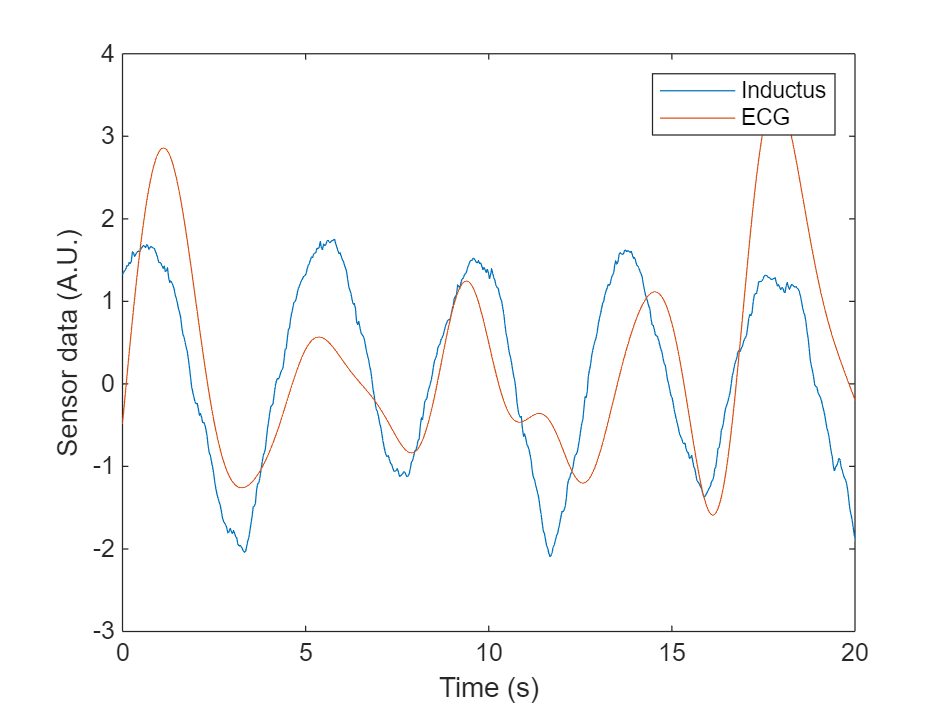

mean_sensor_data = 0.0001*(rs_data - mean(rs_data));

figure;
plot(rs_time-10,mean_sensor_data)
hold on
plot(ECG_clip_time-10,ECG_bp_data)
hold off
legend('Inductus','ECG')
xlim([0 20])
xlabel('Time (s)')
ylabel('Sensor data (A.U.)')